data=readmatrix('sea_ipf.xlsx')

data =          0         0         0   17.5348  312.6494
         0    0.2500         0   14.9983  254.3634
         0    0.5000         0   12.3125  203.4495
         0    0.7500         0   11.0262  199.2583
         0    1.0000         0   11.5872  200.0000
    0.2500         0         0   16.7012  278.1438
    0.2500    0.2500         0   14.4501  219.2368
    0.2500    0.5000         0   11.5139  167.6756
    0.2500    0.7500         0   10.1731  161.3136
    0.2500    1.0000         0   10.7235  162.6218


n_o=data(:,1)

n_o =          0
         0
         0
         0
         0
    0.2500
    0.2500
    0.2500
    0.2500
    0.2500


n_h=data(:,2)

n_h =          0
    0.2500
    0.5000
    0.7500
    1.0000
         0
    0.2500
    0.5000
    0.7500
    1.0000


x={n_o n_h}

x = 1×2 cell array
    {147×1 double}    {147×1 double}


sea = data(:,4)

sea =    17.5348
   14.9983
   12.3125
   11.0262
   11.5872
   16.7012
   14.4501
   11.5139
   10.1731
   10.7235


ipf = data(:,5)

ipf =   312.6494
  254.3634
  203.4495
  199.2583
  200.0000
  278.1438
  219.2368
  167.6756
  161.3136
  162.6218


RSM_SEA0 = @(a,x)( ...
    +a(1).*n_o(1:49) ...  
    +a(2).*n_h(1:49) ...
    +a(3).*n_o(1:49).*n_o(1:49) ...
    +a(4).*n_h(1:49).*n_h(1:49) ...
    +a(5).*n_o(1:49).*n_h(1:49) ...
    +a(6) ...
    );
beta0 = ones(6,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1


a = nlinfit(x,sea(1:49),RSM_SEA0,beta0)

a =    -5.8318
  -17.2001
    4.5284
   10.7852
   -0.8484
   18.1914


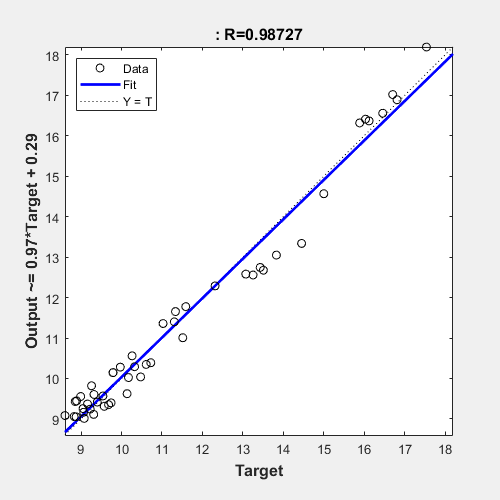


RSMSEA0 = ( ...
    +a(1).*n_o(1:49) ...  
    +a(2).*n_h(1:49) ...
    +a(3).*n_o(1:49).*n_o(1:49) ...
    +a(4).*n_h(1:49).*n_h(1:49) ...
    +a(5).*n_o(1:49).*n_h(1:49) ...
    +a(6) ...
    );
SEA0 = sqrt(mean((RSMSEA0 - sea(1:49)).^2));
plotregression(sea(1:49),RSMSEA0)

RSM_SEA10 = @(b,x)( ...
    +b(1).*n_o(50:98) ...  
    +b(2).*n_h(50:98) ...
    +b(3).*n_o(50:98).*n_o(50:98) ...
    +b(4).*n_h(50:98).*n_h(50:98) ...
    +b(5).*n_o(50:98).*n_h(50:98) ...
    +b(6) ...
    );
beta0 = ones(6,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1


b = nlinfit(x,sea(50:98),RSM_SEA0,beta0)

b =    -5.3185
  -15.8131
    4.0130
    9.8320
   -1.3510
   16.6901


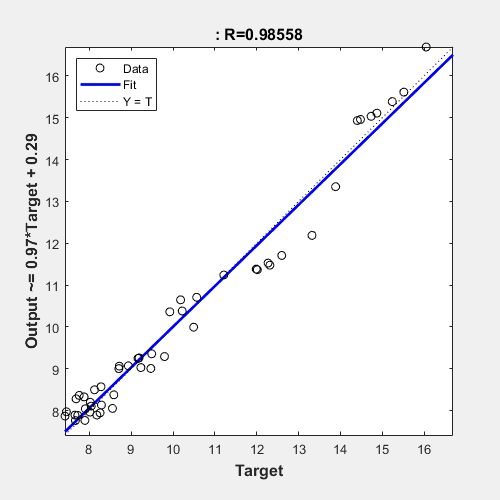


RSMSEA10 = ( ...
    +b(1).*n_o(50:98) ...  
    +b(2).*n_h(50:98) ...
    +b(3).*n_o(50:98).*n_o(50:98) ...
    +b(4).*n_h(50:98).*n_h(50:98) ...
    +b(5).*n_o(50:98).*n_h(50:98) ...
    +b(6));
SEA10 = sqrt(mean((RSMSEA10 - sea(50:98)).^2));
plotregression(sea(50:98),RSMSEA10)

RSM_SEA20 = @(c,x)( ...
    +c(1).*n_o(99:147) ...  
    +c(2).*n_h(99:147) ...
    +c(3).*n_o(99:147).*n_o(99:147) ...
    +c(4).*n_h(99:147).*n_h(99:147) ...
    +c(5).*n_o(99:147).*n_h(99:147) ...
    +c(6) ...
    );
beta0 = ones(6,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1


c = nlinfit(x,sea(99:147),RSM_SEA0,beta0)

c =    -5.9891
  -14.0865
    4.7519
    8.9750
   -1.2920
   15.2618


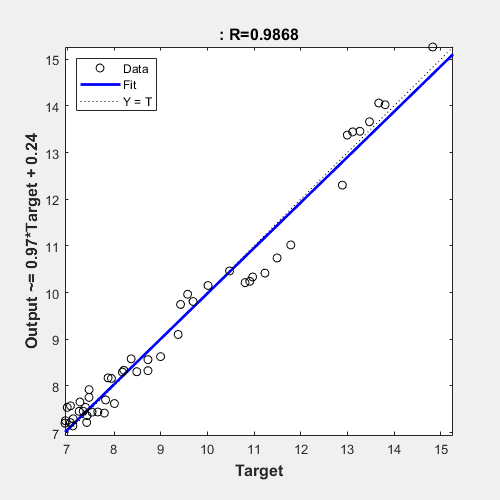


RSMSEA20 = ( ...
    +c(1).*n_o(99:147) ...  
    +c(2).*n_h(99:147) ...
    +c(3).*n_o(99:147).*n_o(99:147) ...
    +c(4).*n_h(99:147).*n_h(99:147) ...
    +c(5).*n_o(99:147).*n_h(99:147) ...
    +c(6) ...
    );
SEA20 = sqrt(mean((RSMSEA20 - sea(99:147)).^2));
plotregression(sea(99:147),RSMSEA20)

RSM_ipf0 = @(d,x)( ...
    +d(1).*n_o(1:49) ...  
    +d(2).*n_h(1:49) ...
    +d(3).*n_o(1:49).*n_o(1:49) ...
    +d(4).*n_h(1:49).*n_h(1:49) ...
    +d(5).*n_o(1:49).*n_h(1:49) ...
    +d(6) ...
    );
beta0 = ones(6,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1


d = nlinfit(x,ipf(1:49),RSM_SEA0,beta0)

d =  -187.1154
 -289.4889
  114.1603
  178.2234
    1.0900
  314.1164


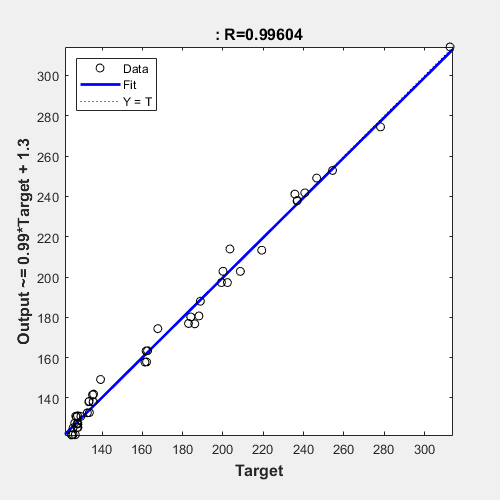


RSMIPF0 = ( ...
    +d(1).*n_o(1:49) ...  
    +d(2).*n_h(1:49) ...
    +d(3).*n_o(1:49).*n_o(1:49) ...
    +d(4).*n_h(1:49).*n_h(1:49) ...
    +d(5).*n_o(1:49).*n_h(1:49) ...
    +d(6) ...
    );
IPF0 = sqrt(mean((RSMIPF0 - ipf(1:49)).^2));
plotregression(ipf(1:49),RSMIPF0)

RSM_ipf10 = @(e,x)( ...
    +e(1).*n_o(50:98) ...  
    +e(2).*n_h(50:98) ...
    +e(3).*n_o(50:98).*n_o(50:98) ...
    +e(4).*n_h(50:98).*n_h(50:98) ...
    +e(5).*n_o(50:98).*n_h(50:98) ...
    +e(6) ...
    );
beta0 = ones(6,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1


e = nlinfit(x,ipf(50:98),RSM_SEA0,beta0)

e =  -117.8297
 -282.0423
   66.4935
  169.6818
    9.8285
  220.7083


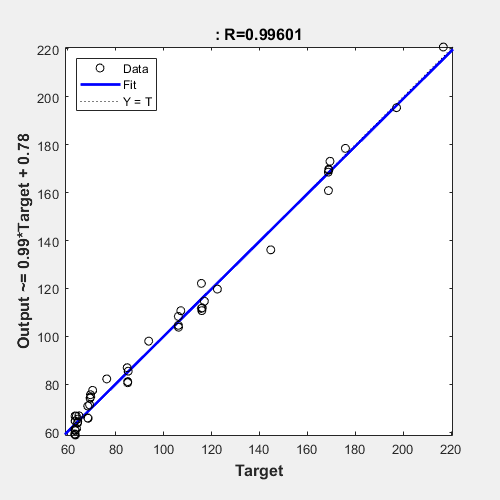


RSMIPF10 = ( ...
    +e(1).*n_o(50:98) ...  
    +e(2).*n_h(50:98) ...
    +e(3).*n_o(50:98).*n_o(50:98) ...
    +e(4).*n_h(50:98).*n_h(50:98) ...
    +e(5).*n_o(50:98).*n_h(50:98) ...
    +e(6) ...
    );
IPF10 = sqrt(mean((RSMIPF10 - ipf(50:98)).^2));
plotregression(ipf(50:98),RSMIPF10)

RSM_ipf20 = @(f,x)( ...
    +f(1).*n_o(99:147) ...  
    +f(2).*n_h(99:147) ...
    +f(3).*n_o(99:147).*n_o(99:147) ...
    +f(4).*n_h(99:147).*n_h(99:147) ...
    +f(5).*n_o(99:147).*n_h(99:147) ...
    +f(6) ...
    );
beta0 = ones(6,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1


f = nlinfit(x,ipf(99:147),RSM_SEA0,beta0)

f =  -157.0367
 -255.7675
   88.0360
  137.3974
   11.0966
  240.6477


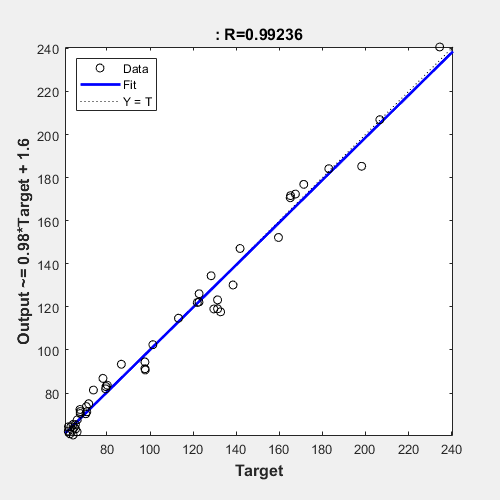


RSMIPF20 = ( ...
    +f(1).*n_o(99:147) ...  
    +f(2).*n_h(99:147) ...
    +f(3).*n_o(99:147).*n_o(99:147) ...
    +f(4).*n_h(99:147).*n_h(99:147) ...
    +f(5).*n_o(99:147).*n_h(99:147) ...
    +f(6) ...
    );
IPF20 = sqrt(mean((RSMIPF20 - ipf(99:147)).^2));
plotregression(ipf(99:147),RSMIPF20)

%for w = 0:(1/9):(1/3)
[i,j]=meshgrid(0:(1/50):1)

i =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800
         0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0

j =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0

k=meshgrid(0:(1/150):(1/3))

k =          0    0.0067    0.0133    0.0200    0.0267    0.0333    0.0400    0.0467    0.0533    0.0600    0.0667    0.0733    0.0800    0.0867    0.0933    0.1000    0.1067    0.1133    0.1200    0.1267    0.1333    0.1400    0.1467    0.1533    0.1600    0.1667    0.1733    0.1800    0.1867    0.1933    0.2000    0.2067    0.2133    0.2200    0.2267    0.2333    0.2400    0.2467    0.2533    0.2600    0.2667    0.2733    0.2800    0.2867    0.2933    0.3000    0.3067    0.3133    0.3200    0.3267
         0    0.0067    0.0133    0.0200    0.0267    0.0333    0.0400    0.0467    0.0533    0.0600    0.0667    0.0733    0.0800    0.0867    0.0933    0.1000    0.1067    0.1133    0.1200    0.1267    0.1333    0.1400    0.1467    0.1533    0.1600    0.1667    0.1733    0.1800    0.1867    0.1933    0.2000    0.2067    0.2133    0.2200    0.2267    0.2333    0.2400    0.2467    0.2533    0.2600    0.2667    0.2733    0.2800    0.2867    0.2933    0.3000    0.3067    0.3133    0.3200    0

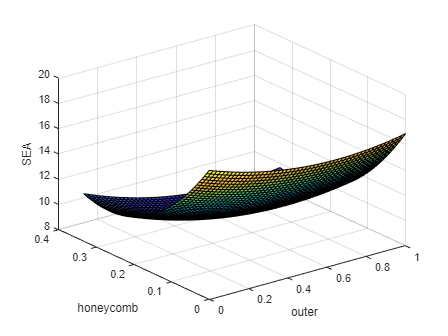

O = i;
H = j;

SEASsurf0 = ( ...
    +a(1).*O ...  
    +a(2).*H ...
    +a(3).*O.*O ...
    +a(4).*H.*H ...
    +a(5).*O.*H ...
    +a(6) ...
    );

SEASsurf10 = ( ...
    +b(1).*O ...  
    +b(2).*H ...
    +b(3).*O.*O ...
    +b(4).*H.*H ...
    +b(5).*O.*H ...
    +b(6) ...
    );

SEASsurf20 = ( ...
    +c(1).*O ...  
    +c(2).*H ...
    +c(3).*O.*O ...
    +c(4).*H.*H ...
    +c(5).*O.*H ...
    +c(6) ...
    );

surf(i,k',SEASsurf0); 
hold off;
% hold on;
% surf(i,k',SEASsurf10); 
% hold on;
% surf(i,k',SEASsurf20);
xlabel('outer') 
ylabel('honeycomb')
zlabel('SEA')
hold off;

%end